## Taller 11 - Ecuaciones diferenciales  

## Invasion Zombie.

**Nombre**: Kevin Giraldo Perez

**ID**: 1040050320

**Email**: kgiraldop@eafit.edu.co

#### Modelo epidemiológico SIRV**.**

**Introduccion** 

El uso de ecuaciones diferenciales en modelos epidemiológicos, como el modelo SIRV (Susceptible-Infectado-Recuperado-Vacunado), es una herramienta crucial para comprender y controlar la propagación de enfermedades. Estos modelos se basan en ecuaciones diferenciales que describen cómo cambia la población en cada una de las categorías mencionadas a lo largo del tiempo.

Este taller se enfoca en la resolución de las ecuaciones diferenciales de un modelo epidemiológico y en el análisis de su comportamiento frente a cambios en factores relevantes utilizando MATLAB como herramienta de analisis.

**Objetivo general**

Resolver numéricamente la ecuación de estado de un modelo epidemiológico SIRV no lineal en un archivo Live Script de MATLAB y analizar el resultado.

**Objetivos especificos**

- Formular las ecuaciones diferenciales del modelo epidemiológico SIRV.

- Implementar estas ecuaciones en MATLAB utilizando funciones y algoritmos adecuados.

- Realizar simulaciones numéricas para ver cómo cambian las poblaciones a lo largo del tiempo bajo diferentes condiciones iniciales y parámetros.

- Analizar el impacto de la vacunación, la variación en las tasas de infección y recuperación, y otras estrategias de intervención en la propagación de la enfermedad.

- Visualizar los resultados de las simulaciones para comprender mejor el comportamiento del modelo.

#### Marco teorico 

El modelo SIRV es una herramienta fundamental para entender la propagación de enfermedades infecciosas causadas por patógenos como virus o bacterias. Se basa en un sistema de ecuaciones diferenciales no lineales que nos permite predecir de manera aproximada cómo evolucionará la enfermedad a lo largo del tiempo. Este modelo divide la población total en cuatro grupos:

- ***Susceptibles ***$S\left(t\right)$: Individuos sanos que pueden contraer la enfermedad si entran en contacto con el patógeno.

- ***Infectados ***$I\left(t\right)$: Individuos que han contraído la enfermedad y pueden transmitirla a los susceptibles.

- ***Recuperados ***$R\left(t\right)$: Individuos que se han recuperado de la enfermedad, ya sea porque son inmunes o porque han fallecido.

- ***Vacunados ***$V\left(t\right)$: Individuos que han sido inmunizados contra el patógeno.

**    Nota:**

        Es importante tener presente que: 

- La población se mantiene constante.

- La tasa de infección, que determina cuántos susceptibles se convierten en infectados con el tiempo, es proporcional al producto de la tasa de transmisión y la tasa de recuperación  $S\left(t\right)*I\left(t\right)$.

**Descripcion del modelo matematico**

El sistema de ecuaciones SIRV es:


$$N=S\left(t\right)+I\left(t\right)+R\left(t\right)+V\left(t\right)$$



$$S^{\prime } =-\beta \;S\left(t\right)\;I\left(t\right)-\delta \;S\left(t\right)$$



$$I^{\prime } =\beta \;S\left(t\right)\;I\left(t\right)-\gamma \;I\left(t\right)$$



$$R^{\prime } =\gamma \;I\left(t\right)$$



$$V^{\prime } =\delta \;S\left(t\right)$$


Donde:

- *S* es la población susceptible.

- *I* es la población infectada.

- *R* es la población recuperada.

- *V* es la población vacunada.

- *β* es la tasa de transmisión de la enfermedad.

- *γ* es la tasa de recuperación.

- *α* es la tasa de vacunación.

Este modelo nos permite entender cómo se propaga una enfermedad en una población dada y evaluar la efectividad de las estrategias de vacunación y control. Además, se puede calcular el número reproductivo básico *R*0 para determinar si una enfermedad se convertirá en una epidemia o no.

Para este caso de estudio se obtuvo que el caso a estudiar es una epidemia.

#### Punto 1 -** Modelo epidemiologico original**

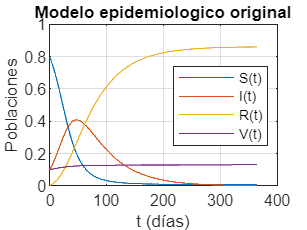

% Parámetros del modelo
beta = 0.1;     % Tasa de transmisión
gamma = 0.02;   % Tasa de recuperación
delta = 0.001;  % Tasa de vacunación

% Sistema de ecuaciones diferenciales
f = @(t, y) [
    -beta * y(1) * y(2) - delta * y(1);
    beta * y(1) * y(2) - gamma * y(2);
    gamma * y(2);
    delta * y(1)
];

% Intervalo de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf;

% Condiciones iniciales para S, I, R y V
Ci = [0.8, 0.1, 0, 0.1];

% Resolución de las ecuaciones diferenciales utilizando ode45
[t1, x1] = ode45(f, tspan, Ci);

% Gráfica de las poblaciones en función del tiempo
figure;
plot(t1, x1(:,1), t1, x1(:,2), t1, x1(:,3), t1, x1(:,4));
title('Modelo epidemiologico original')
xlabel('t (días)');
ylabel('Poblaciones');
legend({'S(t)', 'I(t)', 'R(t)', 'V(t)'}, 'Location', 'Best');
grid on;

 ***    Resultados: ***      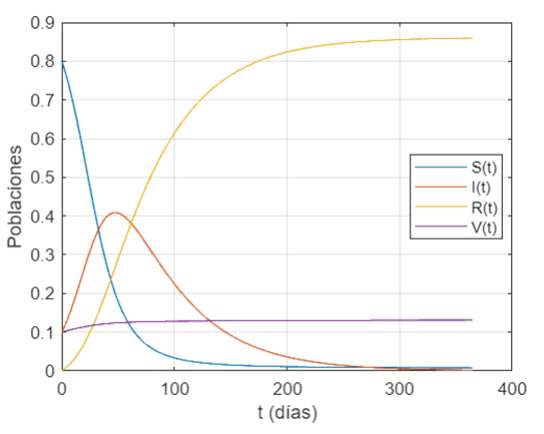

***Analisis: ***La gráfica de resultados muestra claramente cómo cambian las proporciones de los grupos de personas en la población a lo largo del tiempo. Inicia con un pico de personas susceptibles, luego se observa un pico de personas contagiosas y, finalmente, se presenta un pico de personas recuperadas.

Este patrón en la evolución de los grupos de población refleja la dinámica de una epidemia. Al principio, la mayoría de las personas son susceptibles de contraer la enfermedad, lo que resulta en un aumento inicial de las personas infectadas a medida que la enfermedad se propaga. Con el tiempo, a medida que más personas se infectan y se recuperan, el número de personas susceptibles disminuye, y el número de personas recuperadas aumenta.

Este comportamiento es característico de modelos epidemiológicos y refleja cómo una enfermedad infecciosa puede propagarse y finalmente ser controlada a medida que una parte de la población se recupera y desarrolla inmunidad. La visualización de estas dinámicas en la gráfica es fundamental para comprender la evolución de una epidemia y cómo las intervenciones, como la vacunación o el distanciamiento social, pueden influir en su curso.

***   a) Vacunados iniciales para que el numero de infectados no supere el 15%*** 

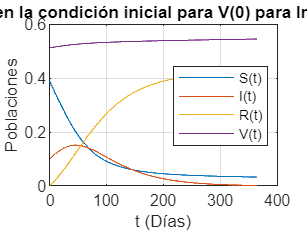

v0 = 0.512; 

Ci = [0.9-v0,  0.1,  0,  v0]; 

[t2,x2] = ode45(f,tspan,Ci);

plot(t2,x2)
title('Cambio en la condición inicial para V(0) para Imax = (0.15)')
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')                                                               % Finalizar superposición de gráficos     

***    Resultados: ***

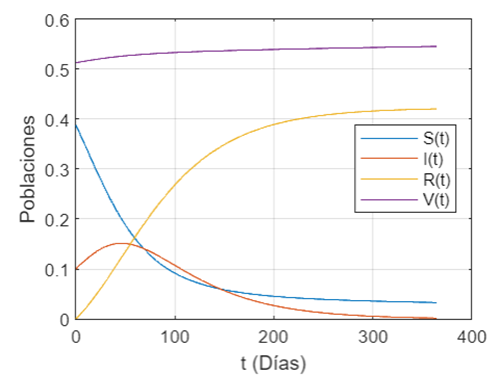

***Analisis: ****E*n la gráfica, se puede apreciar claramente que a medida que aumenta la proporción de personas vacunadas al comienzo del estudio, la altura máxima del pico de personas contagiadas disminuye significativamente. Es decir, la vacunación inicial tiene un efecto positivo en la reducción de la propagación de la enfermedad.

Además, se observa que para limitar el aumento de la tasa de contagios a un máximo del 15% de la población (0.15), es necesario que al menos el 5% (0.51) de la población esté vacunada desde el inicio. Esto significa que una cobertura de vacunación inicial del 51% o más puede ser efectiva para prevenir que la epidemia se propague ampliamente y cause un alto número de contagios.

**Punto 2 - Grafica de poblacion infectada cuando se modifica *****i*****(0).**

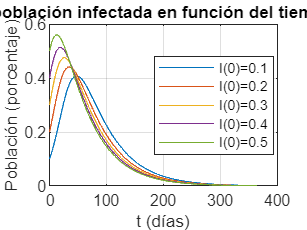

% Declaración de variables simbólicas para S, I, R y V (porcentajes) en función del tiempo t
syms S(t) I(t) R(t) V(t)

% Parámetros del modelo (tasa de contagio, tasa de recuperación y tasa de vacunación)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

% Definición de las ecuaciones del modelo
f1 = -beta * S * I - delta * S; % Cambio en la población susceptible
f2 = beta * S * I - gamma * I; % Cambio en la población infectada
f3 = gamma * I; % Cambio en la población recuperada
f4 = delta * S; % Cambio en la población vacunada

% Convertir las ecuaciones en una función para ode45
f = odeFunction([f1 f2 f3 f4],[S I R V]);

% Intervalo de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf;

% Condiciones iniciales para diferentes valores de I(0)
Ci = [0.8, 0.1, 0, 0.1]; [t1, x1] = ode45(f, tspan, Ci);
Ci = [0.7, 0.2, 0, 0.1]; [t2, x2] = ode45(f, tspan, Ci);
Ci = [0.6, 0.3, 0, 0.1]; [t3, x3] = ode45(f, tspan, Ci);
Ci = [0.5, 0.4, 0, 0.1]; [t4, x4] = ode45(f, tspan, Ci);
Ci = [0.4, 0.5, 0, 0.1]; [t5, x5] = ode45(f, tspan, Ci);

% Gráfico de la población infectada en función del tiempo
figure;
plot(t1, x1(:,2), t2, x2(:,2), t3, x3(:,2), t4, x4(:,2), t5, x5(:,2));
title('población infectada en función del tiempo')
xlabel('t (días)');
ylabel('Población (porcentaje)');
grid on;
legend({'I(0)=0.1', 'I(0)=0.2', 'I(0)=0.3', 'I(0)=0.4', 'I(0)=0.5'}, 'Location', 'Best');

***    Resultados: ***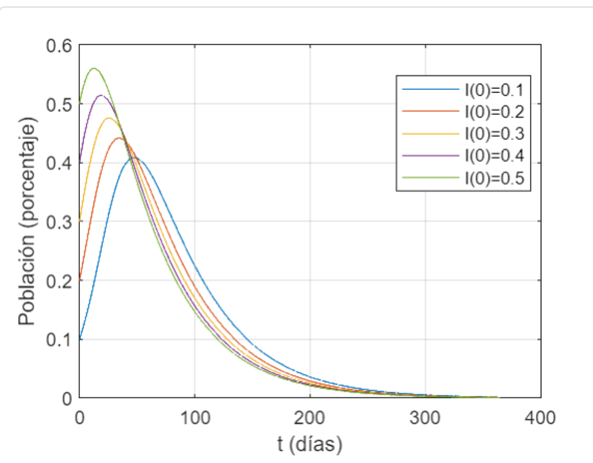 

***    Analisis:*** Los resultados muestran que un aumento en la tasa de personas infectadas al comienzo del estudio acelera la velocidad a la que se alcanza el pico de infectados en la población. En otras palabras, la epidemia se desarrolla más rápidamente cuando hay más personas infectadas inicialmente.

Sin embargo, este aumento inicial también tiene otro efecto importante. Cuando la tasa de personas infectadas es más alta al principio, la diferencia entre el número inicial de infectados y el valor máximo de infectados a lo largo del tiempo es menor. En otras palabras, el pico de infectados no será tan pronunciado ni tan alto como lo sería si la tasa inicial de personas infectadas fuera menor.

Este hallazgo sugiere que, aunque un aumento en la tasa inicial de infección puede acelerar la propagación de una enfermedad, también puede ayudar a limitar la magnitud del pico de infectados, lo que podría ser beneficioso para evitar la saturación de los sistemas de atención médica.

**Punto 3 - Grafica de poblacion infectada cuando se modifica β.**

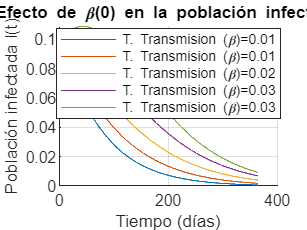

% Declaración de variables simbólicas para S, I, R y V
syms S(t) I(t) R(t) V(t)

% Parámetros del modelo
delta = 0.001; % Tasa de vacunación
gamma = 0.02;  % Tasa de recuperación

% Valores de beta para iterar
beta_values = [0.01, 0.015, 0.02, 0.025, 0.03];

% Parámetros de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf;

% Gráfico inicial
figure
hold on

legend_labels = cell(length(beta_values), 1);

% Iteración para diferentes valores de beta
for counter = 1:length(beta_values)
    beta = beta_values(counter); % Establecer el valor de beta
    
    % Definición de las ecuaciones diferenciales con la tasa de transmisión actual
    f1 = -beta * S * I - delta * S;
    f2 = beta * S * I - gamma * I;
    f3 = gamma * I;
    f4 = delta * S;
    f = odeFunction([f1 f2 f3 f4], [S I R V]);

    % Condiciones iniciales
    initial_conditions = [0.8, 0.1, 0, 0.1];

    % Resolver el sistema de ecuaciones diferenciales con la tasa de transmisión actualizada
    [time, output] = ode45(f, tspan, initial_conditions);

    % Gráfico con colores diferentes para cada curva y etiquetas para la leyenda
    plot(time, output(:, 2), 'DisplayName', sprintf('T. Transmision (\\beta)=%.2f', beta))
    
    % Almacenar las etiquetas de la leyenda
    legend_labels{counter} = sprintf('T. Transmision (\\beta)=%.2f', beta);
end

grid on
title('Efecto de \beta(0) en la población infectada')
xlabel("Tiempo (días)")
ylabel("Población infectada I(t)")
legend(legend_labels, 'Location', 'Best')

***    Resultados: ***

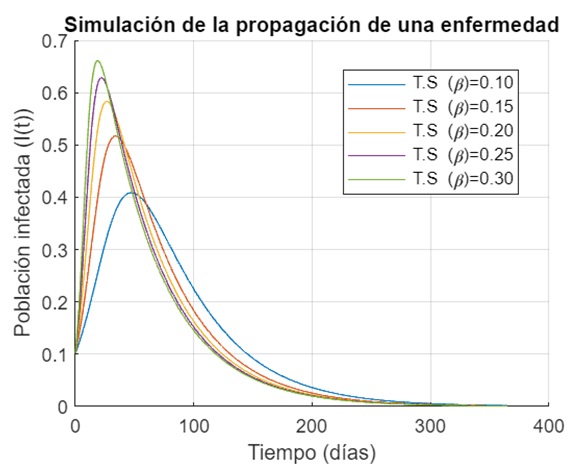

***    a) Cuál valor máximo de beta (diferente de cero) se evitaría una epidemia  ***

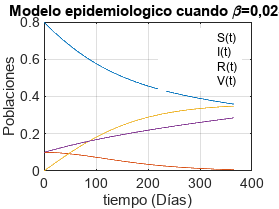

% Declaración de variables simbólicas para S, I, R y V en función del tiempo t
syms S(t) I(t) R(t) V(t)

% Parámetros del modelo
beta = 0.025; % Tasa de transmisión
gamma = 0.02; % Tasa de recuperación
delta = 0.001; % Tasa de vacunación

% Intervalo de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf;

% Definición de las ecuaciones diferenciales
f1 = -beta * S * I - delta * S;
f2 = beta * S * I - gamma * I;
f3 = gamma * I;
f4 = delta * S;

% Convertir las ecuaciones en una función de MATLAB
f = odeFunction([f1 f2 f3 f4], [S I R V]);

% Condiciones iniciales
Ci = [0.8 0.1 0 0.1];

% Resolver el sistema de ecuaciones diferenciales
[t1, x1] = ode45(f, tspan, Ci);

% Graficar las poblaciones en función del tiempo
figure;
plot(t1, x1)
title('Modelo epidemiologico cuando \beta=0,025')
xlabel('tiempo (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)', 'I(t)', 'R(t)', 'V(t)'}, 'Location', 'Best')

 ***    Analisis: *** Un valor de beta igual a 0.025 es suficiente para prevenir la propagación continua de la enfermedad, lo que sugiere que la enfermedad no se propaga de manera sostenible en la población y, por lo tanto, no se considera que haya una endemia.

**Punto 4 - Grafica de poblacion infectada cuando se modifica γ **

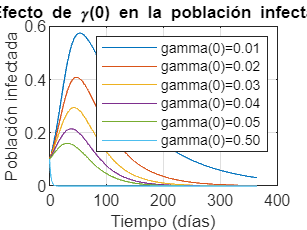

% Declaración de variables simbólicas para S, I, R y V
syms S(t) I(t) R(t) V(t);

% Parámetros del modelo
beta = 0.1; % Tasa de transmisión
delta = 0.001; % Tasa de vacunación
gamma_values = [0.01, 0.02, 0.03, 0.04, 0.05, 0.5]; % Valores de gamma a probar

% Parámetros de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf; % Vector de tiempo

% Condiciones iniciales
Ci = [0.8, 0.1, 0, 0.1]; 

% Inicialización de variables para almacenar los resultados
x = zeros(length(gamma_values), length(tspan));

% Resolución del sistema de ecuaciones diferenciales para diferentes valores de gamma
for i = 1:length(gamma_values)
    gamma_temp = gamma_values(i);
    f1 = -beta * S * I - delta * S;
    f2 = beta * S * I - gamma_temp * I;
    f3 = gamma_temp * I;
    f4 = delta * S;
    f = odeFunction([f1 f2 f3 f4], [S I R V]);
    [t, x_temp] = ode45(f, tspan, Ci);
    x(i, :) = x_temp(:, 2); % Almacena la población infectada en cada iteración
end

% Gráfico
figure
plot(tspan, x)
xlabel('Tiempo (días)')
ylabel('Población infectada')
title('Efecto de \gamma(0) en la población infectada')
grid on
legend(arrayfun(@(g) sprintf('gamma(0)=%.2f', g), gamma_values, 'UniformOutput', false))

***    Resultados: ***

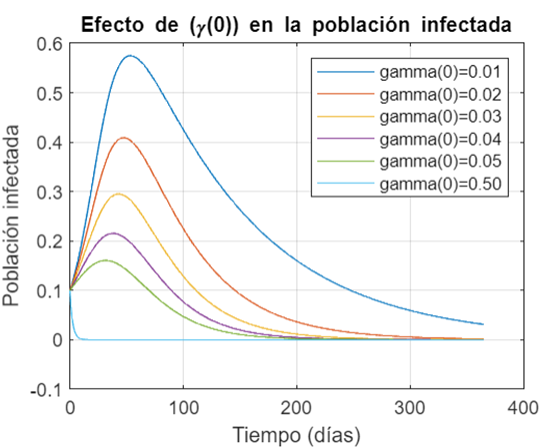

***    a) ¿Con que valor minimo de ***$\gamma \left(0\right)=?$*** se evitaria la epidemia?***

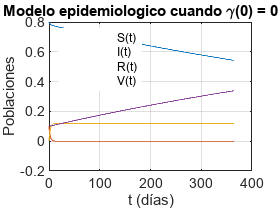

% Parámetros del modelo
beta = 0.1;     % Tasa de transmisión
gamma = 0.5;   % Tasa de recuperación
delta = 0.001;  % Tasa de vacunación

% Sistema de ecuaciones diferenciales
f = @(t, y) [
    -beta * y(1) * y(2) - delta * y(1);
    beta * y(1) * y(2) - gamma * y(2);
    gamma * y(2);
    delta * y(1)
];

% Intervalo de tiempo
ti = 0;
tf = 365;
tspan = ti:1:tf;

% Condiciones iniciales para S, I, R y V
Ci = [0.8, 0.1, 0, 0.1];

% Resolución de las ecuaciones diferenciales utilizando ode45
[t1, x1] = ode45(f, tspan, Ci);

% Gráfica de las poblaciones en función del tiempo
figure;
plot(t1, x1(:,1), t1, x1(:,2), t1, x1(:,3), t1, x1(:,4));
title('Modelo epidemiologico cuando \gamma(0) = 0,05')
xlabel('t (días)');
ylabel('Poblaciones');
legend({'S(t)', 'I(t)', 'R(t)', 'V(t)'}, 'Location', 'Best');
grid on;

***    Analisis: ***Después de realizar los análisis, se puede observar en la gráfica que cuando la tasa de recuperación (gamma) tiene un valor de 0.05, no se desarrolla la epidemia. Esto se evidencia en la gráfica, ya que el número máximo de infectados se presenta en el tiempo inicial (t = 0), y a medida que el tiempo avanza, la tasa de infectados disminuye.

**Punto 5 - Grafica de poblacion infectada cuando se modifica **$\delta$

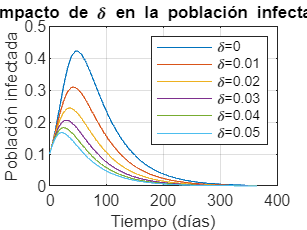

% Declaración de variables simbólicas para S, I, R y V
syms S(t) I(t) R(t) V(t);

% Parámetros del modelo
beta = 0.1;
gamma = 0.02;

tmin = 0;
tmax = 365;
tspan = tmin:1:tmax; % Vector de tiempo

Ci = [0.8, 0.1, 0, 0.1]; % Condiciones iniciales

% Valores de delta a probar
delta_values = [0, 0.01, 0.02, 0.03, 0.04, 0.05];

% Inicialización de matriz para almacenar los resultados
x = zeros(length(tspan), length(delta_values));

% Resolución del sistema de ecuaciones diferenciales para diferentes valores de delta
for i = 1:length(delta_values)
    delta_temp = delta_values(i);
    f1 = -beta * S * I - delta_temp * S;
    f2 = beta * S * I - gamma * I;
    f3 = gamma * I;
    f4 = delta_temp * S;
    f = odeFunction([f1 f2 f3 f4], [S I R V]);
    [~, x_temp] = ode45(f, tspan, Ci);
    x(:, i) = x_temp(:, 2); % Almacena la población infectada en cada iteración
end

% Gráfico
figure
plot(tspan, x)
xlabel('Tiempo (días)')
ylabel('Población infectada')
grid on
legend('\delta=0', '\delta=0.01', '\delta=0.02', '\delta=0.03', '\delta=0.04', '\delta=0.05')
title('Impacto de \delta en la población infectada')

***    Resultados:***

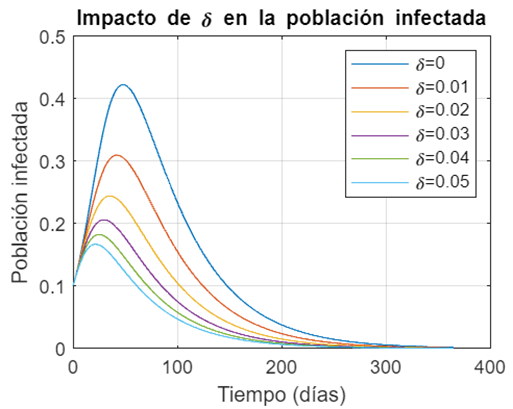 

***    a) Cuando ***$\delta \left(0\right)=0,032$ 

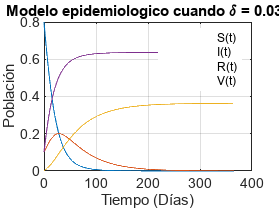

% Declaración de variables simbólicas para S, I, R y V
syms S(t) I(t) R(t) V(t);

% Parámetros del modelo
beta = 0.1;             % Tasa de transmisión
gamma = 0.02;           % Tasa de recuperación
delta = 0.032;          % Tasa de vacunación 

% Condiciones iniciales
Ci = [0.8, 0.1, 0, 0.1];

% Definición de las ecuaciones diferenciales
f1 = -beta * S * I - delta * S;
f2 = beta * S * I - gamma * I;
f3 = gamma * I;
f4 = delta * S;

% Convertir las ecuaciones diferenciales en una función MATLAB
f = odeFunction([f1 f2 f3 f4], [S I R V]);

% Resolver el sistema de ecuaciones diferenciales
[t1, x1] = ode45(f, tspan, Ci);

% Gráfico
figure
plot(t1, x1)
title('Modelo epidemiologico cuando \delta = 0.032')
xlabel('Tiempo (Días)')
ylabel('Población')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

***    Analisis : *** Como se refleja en los resultados, un aumento en la tasa de vacunación conlleva una reducción en el valor pico de la tasa de infectados. Además, para mantener la tasa de infectados por debajo del 20% de la población total, es necesario tener una tasa de vacunación mínima de al menos 0.032.

Esto indica que una alta tasa de vacunación es efectiva para controlar la propagación de la enfermedad y limitar el número de personas infectadas.

#### Conclusion 

- La vacunación inicial del 10% de la población y su posterior aumento a lo largo del tiempo tiene un impacto significativo en la evolución de la epidemia. Cuando el porcentaje de vacunados alcanza aproximadamente el 52%, se evita que los infectados superen el 15% de la poblacion y con esto se evita que la epidemia zombie se propague por completo. Es importante anotar que, incluso una pequeña cantidad de vacunados contribuye a reducir la gravedad de la epidemia y evita la saturación de los hospitales.

- Cambiar el número inicial de infectados (I(0)) afecta directamente a la población susceptible (S(0)) y, por lo tanto, la propagación de la enfermedad. 

- El aumento de la tasa de transmisión (β) y la cantidad inicial de infectados (I(0)) tienen efectos similares en la propagación de la epidemia. Ambos conducen a picos más altos y más tempranos en la propagación de la enfermedad. El valor minimo de (β), necesario para evitar la epidemia es de 0,025.

- La tasa de recuperación y aislamiento (γ) desempeña un papel importante en la propagación de la epidemia. Una baja tasa de (γ) conduce a picos de infección más acentuados y una propagación más rápida de la enfermedad. El valor minimo de (γ), necesario para evitar la epidemia es de 0,5.

- La tasa de vacunación (δ) es fundamental para controlar la epidemia. Una tasa de vacunación adecuada puede prevenir la propagación de la enfermedad. En este caso el valor mínimo de  (δ) para que el pico de infectados llegue a 0.2 es de aproximadamente 0.0322.

**Cibergrafia**

- [https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology) 

- [https://es.wikipedia.org/wiki/Modelo_SIR](https://es.wikipedia.org/wiki/Modelo_SIR) 

- [https://scielosp.org/article/rcsp/2020.v46suppl1/e2597/es/](https://scielosp.org/article/rcsp/2020.v46suppl1/e2597/es/) 

- [https://repositorio.unican.es/xmlui/bitstream/handle/10902/7125/Andrea%20Garcia%20Pi%C3%B1era.pdf](https://repositorio.unican.es/xmlui/bitstream/handle/10902/7125/Andrea%20Garcia%20Pi%C3%B1era.pdf) 